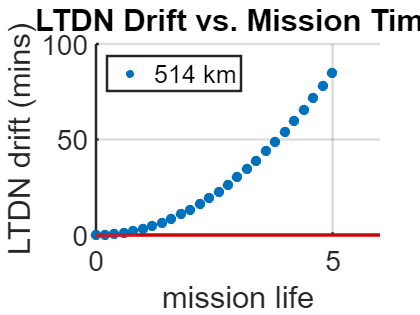

clear; close all; clc;

R_E = 6378.137;
mu_E = 398600.4417;
J2 = 1.08263e-3;
h_init = 514;
alpha_dot = 0.9856;

dadt = -0.0337*365.2422;

figure();

for index = 1:length(h_init)
    a = R_E + h_init(index);
    
    LTDN = deg2rad(11.5*15);
    i = acos(-0.098922 * (1 + (h_init(index) / R_E))^(7/2));
    n = rad2deg(sqrt(mu_E/a^3))*86400;
    i_sun = deg2rad(23.44);
    
    
    didt = (3/16)*(alpha_dot^2/n)*sin(i)*(1+cos(i_sun))^2*sin(2.*LTDN)*365.2422;
   
    t = 0:0.2:5;


    dLTDN = (-7*(0.9856*365.2422/a)*dadt(index)-4*pi*tan(i)*didt)*(t.^2);
    


    scatter(t, dLTDN, 60, 'filled')
    hold on
    grid on
    % ylim([-15 15])
    title("LTDN Drift vs. Mission Time")
    ylabel('LTDN drift (mins)')
    xlabel('mission life')
    ax=gca;
    ax.LineWidth=2;
    ax.FontSize=21;
end
yline(0,'r','linewidth',3)
legend('514 km',Location='northwest')